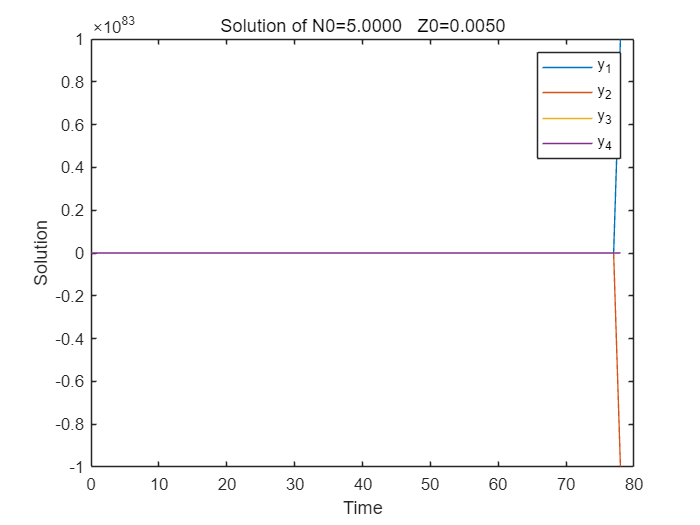

% 定义时间步长和时间范围
h = 1; % 时间步长
t0 = 0; % 初始时间
tf = 1000; % 终止时间
t = t0:h:tf; % 时间向量

%初始化参数
a = 0.2;
b = 0.04;
c = 0.2;
d = 0.6;
e1 = 0.03;
e2 = 0.03;
s = 0.04;
k = 0.05;
w1 = 0.05;
w2 = 0.05;
lambda1 = 0.035;
lambda2 = 0.5;
mu = 0.06;
alpha = 0.25;
beta = 0.25;
N0 = 5;
K = 5;
Z0 = 0.005;
gama = 0.1;

% 初始化解向量
y = zeros(4, length(t)); 
y(:, 1) = [N0; 0.05; 0.5; Z0]; % 初始条件

% 定义方程组
f = @(t, y) [
    max(0,-a*y(1)*(1-y(2)/K)*y(2)/(e1+y(1))-c*y(1)*y(3)/(e2+y(1))+gama*k*(y(2)));
    a*y(1)*(1-y(2)/K)*y(2)/(e1+y(1))-b*y(2)*y(4)/(lambda1+y(2))-w1*y(2)+w2*y(3)-(s+k)*y(2);
    c*y(1)*y(3)/(e2+y(1))-d*y(3)*y(4)/(lambda2+y(3))-w2*y(3)+w1*y(2)-s*y(3);
    (alpha*b*y(2)/(lambda1+y(2))+beta*d*y(3)/(lambda2+y(3)))*y(4)-mu*y(4)*y(4);
];

% RK4 方法
for i = 1:length(t)-1
    k1 = h * f(t(i), y(:, i));
    k2 = h * f(t(i) + h/2, y(:, i) + k1/2);
    k3 = h * f(t(i) + h/2, y(:, i) + k2/2);
    k4 = h * f(t(i) + h, y(:, i) + k3);
    y(:, i+1) = y(:, i) + (k1 + 2*k2 + 2*k3 + k4) / 6;
end

% 绘制结果
plot(t, y);
legend('y_1', 'y_2', 'y_3', 'y_4');
xlabel('Time');
ylabel('Solution');
N_str = sprintf('%.4f', N0);
Z_str = sprintf('%.4f', Z0);
title(['Solution of N0=',N_str,'   Z0=',Z_str]);